close all; clear; clc;

# P80 characterization tests 4 bat STv2.1 ALL cont. recording tests

(10% throttle to 90% throttle multiple times  **- Record settled**)

**file name**: STv2_1_P8027d_20181115_1.mlx

**keywords:** 

**date of test:** 20180928

**file created by:** 20181001, Edmonds

**last updated on:** YYYYMMDD

**primary purpose:** 

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** 

**Notes:** 

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
p = 0.002377;                  %[slugs/ft^3]
% If this wasn't recorded on the day of the test use 0.00228344448402635. 
% Record this in the notes section above

% Motor Specs
radius = 27/12;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data- Test 1

This format assumes that the data output from RC Benchmark has not been changed

load('STv2_1_P8027d_20181115_1.mat');
time1_1 = STv2_1_P8027d_20181115_1(:,1);                       % [sec]
PWM1_1 = STv2_1_P8027d_20181115_1(:,2);                        % [micro sec]
Q1_1 = STv2_1_P8027d_20181115_1(:,4);                          % [ft.lbf]
T1_1 = STv2_1_P8027d_20181115_1(:,5);                          % [lbf]
Input_V1_1 = STv2_1_P8027d_20181115_1(:,6);                    % [Volts]
Input_A1_1 = STv2_1_P8027d_20181115_1(:,7);                    % [Amps]
rot_speed_rpm1_1 = STv2_1_P8027d_20181115_1(:,8);              % [RPM]
% convert to RPM for plotting purposes
rot_speed_rad1_1 = rot_speed_rpm1_1 .* (pi/30);   % [rad/sec]
P_in_W1_1 = STv2_1_P8027d_20181115_1(:,9);                     % [Watts]
P_out_W1_1 = STv2_1_P8027d_20181115_1(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out1_1 = P_out_W1_1 .* 0.7478;                  % [ft.lbf/sec]         
P_in1_1 = P_in_W1_1 .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff1_1 = STv2_1_P8027d_20181115_1(:,11);                 % [%]
Prop_Eff1_ = STv2_1_P8027d_20181115_1(:,12);                  % [lbf/Watts]
Overall_Eff1_1 = STv2_1_P8027d_20181115_1(:,13);               % [lbf/Watts]  
ESC_Temp1_1 = STv2_1_P8027d_20181115_1(:,14);                  % [F]
Motor_Temp1_1 = STv2_1_P8027d_20181115_1(:,15);                % [F]

disk_loading1_1 = T1_1 ./ area;                     % [lb/sq.ft]

Settling_time1_1 = STv2_1_P8027d_20181115_1(:,17); % [s]
Max_Acc1_1 = STv2_1_P8027d_20181115_1(:,18);      % [RPM]

C_T1_1 = T1_1 ./ (p .* area * (rot_speed_rad1_1 * radius).^2);
C_P1_1 = P_out1_1 ./ (p .* area .* (rot_speed_rad1_1 .* radius).^3);
C_Q1_1 = Q1_1 ./ (p .* area .* (rot_speed_rad1_1 .* radius).^(2) .* radius);

throttle1 = (PWM1_1 - 1000) ./ 10;

## Measured Data - Test 2

This format assumes that the data output from RC Benchmark has not been changed

load('STv2_1_P8027d_20181115_2.mat');
time2_1 = STv2_1_P8027d_20181115_2(:,1);                       % [sec]
PWM2_1 = STv2_1_P8027d_20181115_2(:,2);                        % [micro sec]
Q2_1 = STv2_1_P8027d_20181115_2(:,4);                          % [ft.lbf]
T2_1 = STv2_1_P8027d_20181115_2(:,5);                          % [lbf]
Input_V2_1 = STv2_1_P8027d_20181115_2(:,6);                    % [Volts]
Input_A2_1 = STv2_1_P8027d_20181115_2(:,7);                    % [Amps]
rot_speed_rpm2_1 = STv2_1_P8027d_20181115_2(:,8);              % [RPM]
% convert to RPM for plotting purposes
rot_speed_rad2_1 = rot_speed_rpm2_1 .* (pi/30);   % [rad/sec]
P_in_W2_1 = STv2_1_P8027d_20181115_2(:,9);                     % [Watts]
P_out_W2_1 = STv2_1_P8027d_20181115_2(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out2_1 = P_out_W2_1 .* 0.7478;                  % [ft.lbf/sec]         
P_in2_1 = P_in_W2_1 .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff2_1 = STv2_1_P8027d_20181115_2(:,11);                 % [%]
Prop_Eff2_1 = STv2_1_P8027d_20181115_2(:,12);                  % [lbf/Watts]
Overall_Eff2_1 = STv2_1_P8027d_20181115_2(:,13);               % [lbf/Watts]  
ESC_Temp2_1 = STv2_1_P8027d_20181115_2(:,14);                  % [F]
Motor_Temp2_1 = STv2_1_P8027d_20181115_2(:,15);                % [F]

disk_loading2_1 = T2_1 ./ area;                     % [lb/sq.ft]

Settling_time2_1 = STv2_1_P8027d_20181115_2(:,17); % [s]
Max_Acc2_1 = STv2_1_P8027d_20181115_2(:,18);      % [RPM]

C_T2_1 = T2_1 ./ (p .* area * (rot_speed_rad2_1 * radius).^2);
C_P2_1 = P_out2_1 ./ (p .* area .* (rot_speed_rad2_1 .* radius).^3);
C_Q2_1 = Q2_1 ./ (p .* area .* (rot_speed_rad2_1 .* radius).^(2) .* radius);

throttle2 = (PWM2_1 - 1000) ./ 10;

## Measured Data - Test 3

This format assumes that the data output from RC Benchmark has not been changed

load('STv2_1_P8027d_20181115_3.mat');
time3_1 = STv2_1_P8027d_20181115_3(:,1);                       % [sec]
PWM3_1 = STv2_1_P8027d_20181115_3(:,2);                        % [micro sec]
Q3_1 = STv2_1_P8027d_20181115_3(:,4);                          % [ft.lbf]
T3_1 = STv2_1_P8027d_20181115_3(:,5);                          % [lbf]
Input_V3_1 = STv2_1_P8027d_20181115_3(:,6);                    % [Volts]
Input_A3_1 = STv2_1_P8027d_20181115_3(:,7);                    % [Amps]
rot_speed_rpm3_1 = STv2_1_P8027d_20181115_3(:,8);              % [RPM]
% convert to RPM for plotting purposes
rot_speed_rad3_1 = rot_speed_rpm3_1 .* (pi/30);   % [rad/sec]
P_in_W3_1 = STv2_1_P8027d_20181115_3(:,9);                     % [Watts]
P_out_W3_1 = STv2_1_P8027d_20181115_3(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out3_1 = P_out_W3_1 .* 0.7478;                  % [ft.lbf/sec]         
P_in3_1 = P_in_W3_1 .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff3_1 = STv2_1_P8027d_20181115_3(:,11);                 % [%]
Prop_Eff3_1 = STv2_1_P8027d_20181115_3(:,12);                  % [lbf/Watts]
Overall_Eff3_1 = STv2_1_P8027d_20181115_3(:,13);               % [lbf/Watts]  
ESC_Temp3_1 = STv2_1_P8027d_20181115_3(:,14);                  % [F]
Motor_Temp3_1 = STv2_1_P8027d_20181115_3(:,15);                % [F]

disk_loading3_1 = T3_1 ./ area;                     % [lb/sq.ft]

Settling_time3_1 = STv2_1_P8027d_20181115_3(:,17); % [s]
Max_Acc3_1 = STv2_1_P8027d_20181115_3(:,18);      % [RPM]

C_T3_1 = T3_1 ./ (p .* area * (rot_speed_rad3_1 * radius).^2);
C_P3_1 = P_out3_1 ./ (p .* area .* (rot_speed_rad3_1 .* radius).^3);
C_Q3_1 = Q3_1 ./ (p .* area .* (rot_speed_rad3_1 .* radius).^(2) .* radius);

throttle3 = (PWM3_1 - 1000) ./ 10;

## Plots

The following are standard charts. Remove, add, and edit as needed.

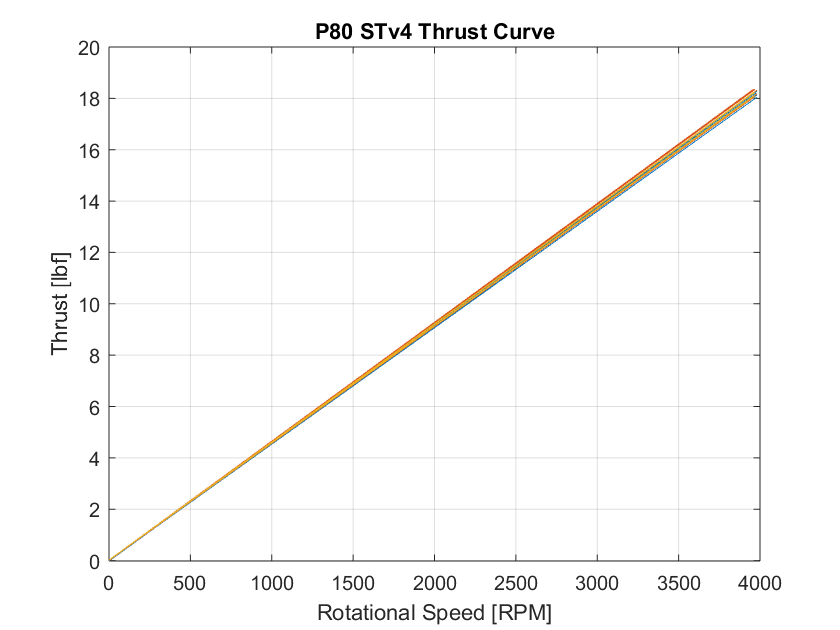

figure(1)
plot(rot_speed_rpm1_1, T1_1, rot_speed_rpm2_1, T2_1, rot_speed_rpm3_1, T3_1); title('P80 STv4 Thrust Curve'); 
xlabel('Rotational Speed [RPM]'); ylabel('Thrust [lbf]'); grid('on');

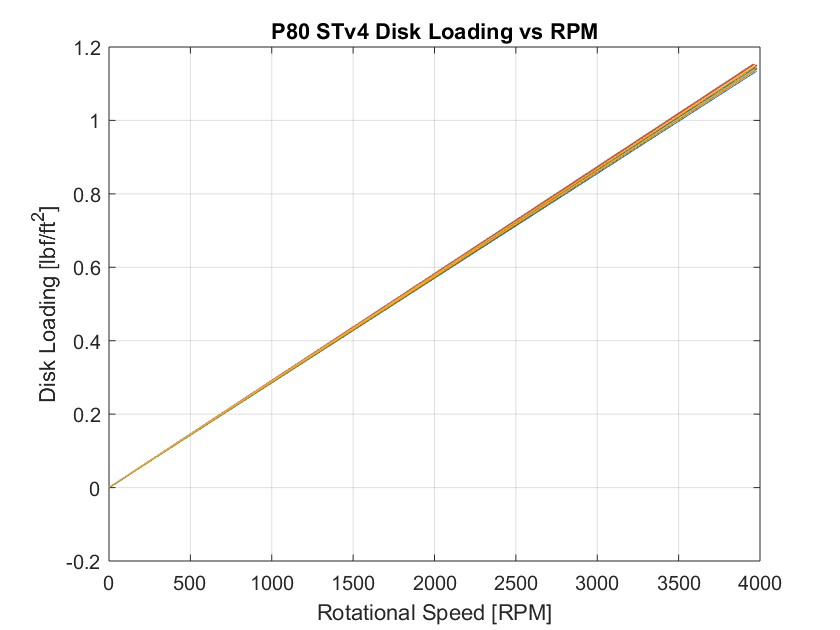


figure(2)
plot(rot_speed_rpm1_1, disk_loading1_1, rot_speed_rpm2_1, disk_loading2_1, rot_speed_rpm3_1, disk_loading3_1); title('P80 STv4 Disk Loading vs RPM');
xlabel('Rotational Speed [RPM]'); ylabel('Disk Loading [lbf/ft^2]')
grid('on');

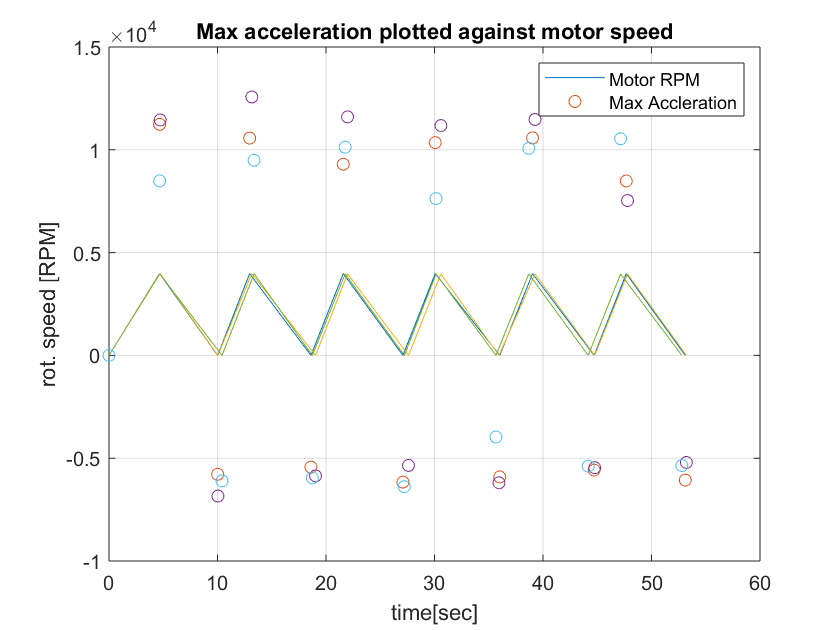


figure(3)
plot(time1_1, rot_speed_rpm1_1, time1_1, Max_Acc1_1, 'o', time2_1, rot_speed_rpm2_1, time2_1, Max_Acc2_1, 'o', time3_1, rot_speed_rpm3_1, time3_1, Max_Acc3_1, 'o');
title('Max acceleration plotted against motor speed')
xlabel('time[sec]'); ylabel('rot. speed [RPM]'); 
legend('Motor RPM', 'Max Accleration'); grid('on');

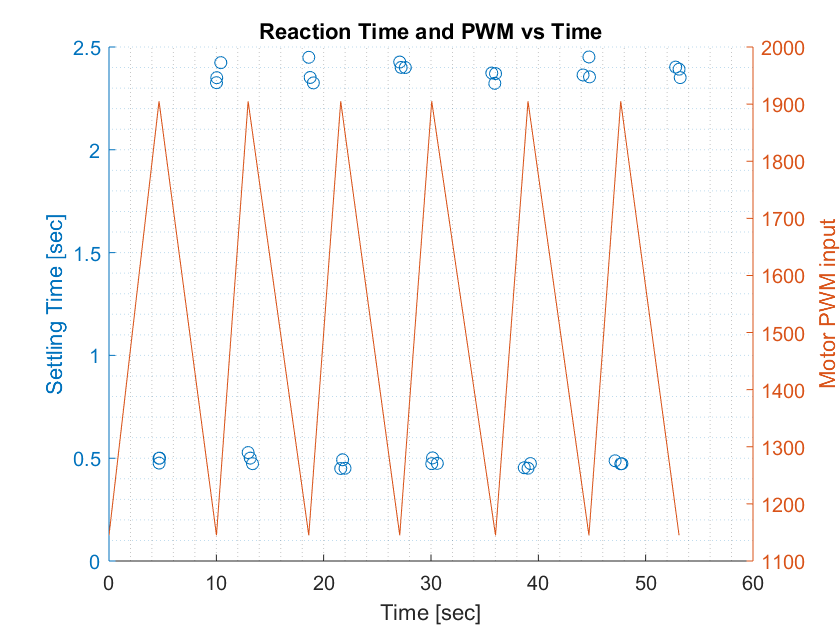


figure(4)
hold on
yyaxis left
plot(time1_1,Settling_time1_1, 'o', time2_1,Settling_time2_1, 'o', time3_1,Settling_time3_1, 'o');
ylabel('Settling Time [sec]');
yyaxis right
plot(time1_1, PWM1_1);
ylabel('Motor PWM input');
title('Reaction Time and PWM vs Time');
xlabel('Time [sec]');
grid('minor');
hold off

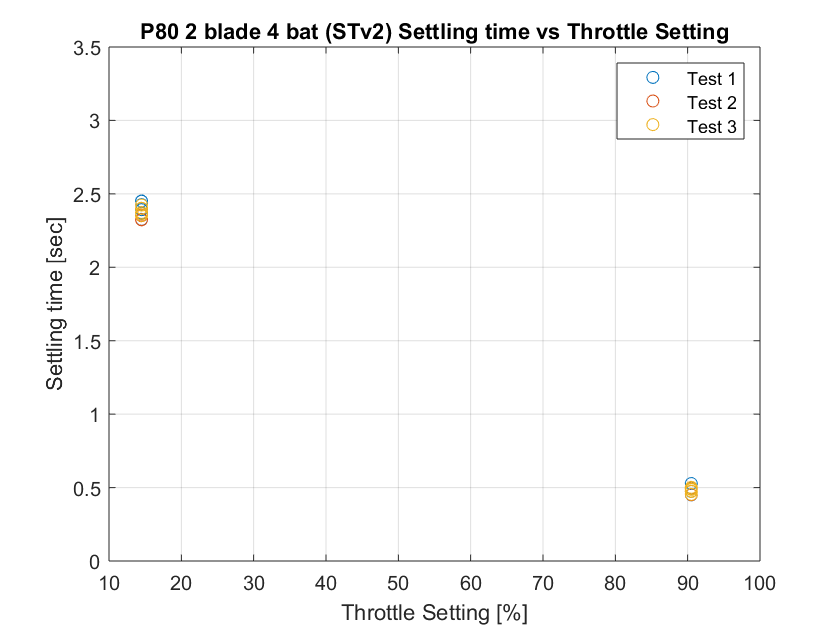


figure(5)
plot(throttle1, Settling_time1_1, 'o', throttle2, Settling_time2_1, 'o', throttle3, Settling_time3_1, 'o');
title('P80 2 blade 4 bat (STv2) Settling time vs Throttle Setting');
xlabel('Throttle Setting [%]'); ylabel('Settling time [sec]');
legend('Test 1', 'Test 2', 'Test 3');
ylim([0 3.5]); grid('on');

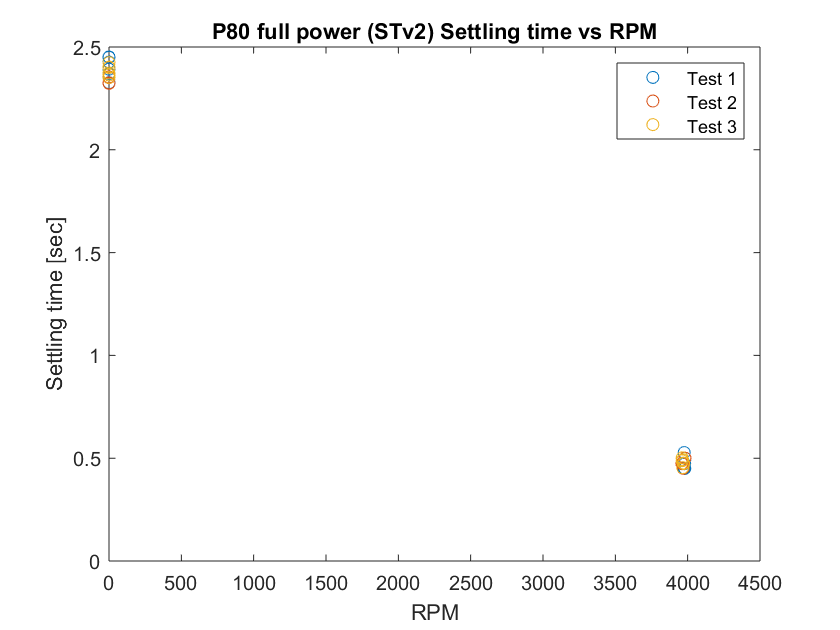


figure(6)
plot(rot_speed_rpm1_1, Settling_time1_1, 'o', rot_speed_rpm2_1, Settling_time2_1, 'o', rot_speed_rpm3_1, Settling_time3_1, 'o');
title('P80 full power (STv2) Settling time vs RPM');
xlabel('RPM'); ylabel('Settling time [sec]');
legend('Test 1', 'Test 2', 'Test 3'); xlim ([0 4500]);